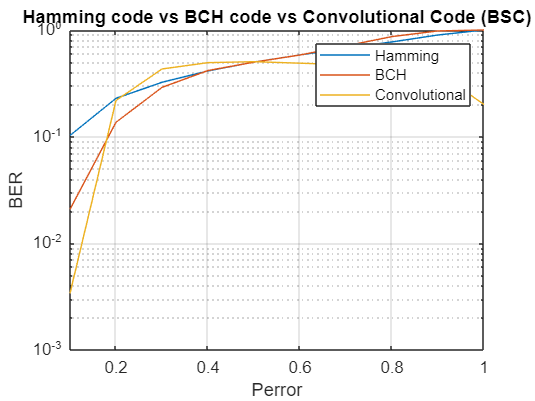

clear;
clc;
hamming_awgn = load("Hamming_AWGN.mat","error_arr");
hamming_awgn = deal(hamming_awgn.error_arr);
hamming_bsc = load("Hamming_BSC.mat","error_arr");
hamming_bsc = deal(hamming_bsc.error_arr);

bch_awgn = load("BCH_AWGN.mat","error_arr");
bch_awgn = deal(bch_awgn.error_arr);
bch_bsc = load("BCH_BSC.mat","error_arr");
bch_bsc = deal(bch_bsc.error_arr);


conv_awgn = load("Conv_AWGN.mat","error_arr");
conv_awgn = deal(conv_awgn.error_arr);
conv_bsc = load("Conv_BSC.mat","error_arr");
conv_bsc = deal(conv_bsc.error_arr);

SNR = [0:2:10];
p=[0:0.1:1];

semilogy(p,hamming_bsc)
hold on
semilogy(p,bch_bsc)
semilogy(p,conv_bsc)
legend("Hamming","BCH","Convolutional")
xlabel("Perror")
ylabel("BER")
title("Hamming code vs BCH code vs Convolutional Code (BSC)")
grid on;
xlim([0.1 1])

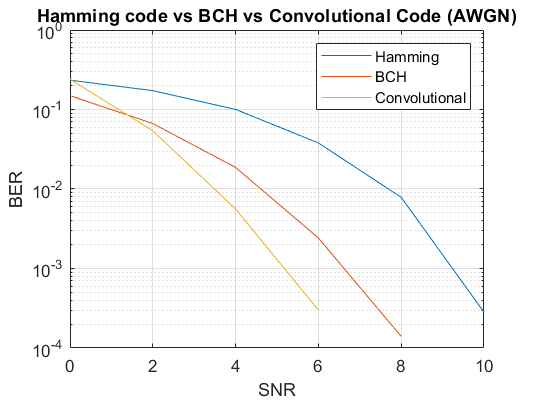



figure
semilogy(SNR,hamming_awgn)
hold on
semilogy(SNR,bch_awgn)
semilogy(SNR,conv_awgn)
legend("Hamming","BCH","Convolutional")
xlabel("SNR")
ylabel("BER")
title("Hamming code vs BCH vs Convolutional Code (AWGN)")
grid on;